## contrast stretching

enhance contrast

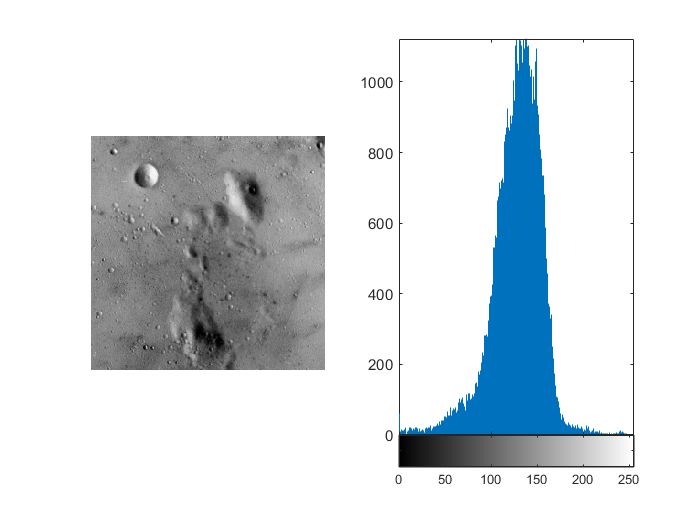

clear; clc;
moon = imread("moon surface.tiff");

figure;
subplot(1, 2, 1); imshow(moon);
subplot(1, 2, 2); imhist(moon);

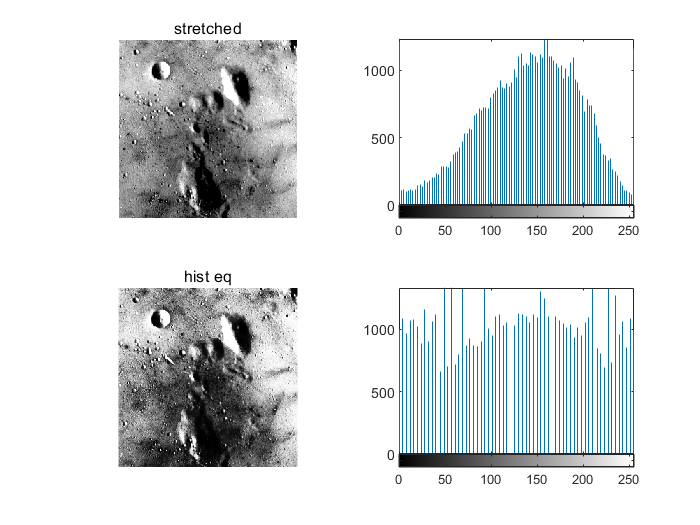

moon_stretch = imadjust(moon, [75/255, 175/255], [0.0, 1.0]);
moon_eq = histeq(moon);

figure;
subplot(2, 2, 1); imshow(moon_stretch); title('stretched');
subplot(2, 2, 2); imhist(moon_stretch); 
subplot(2, 2, 3); imshow(moon_eq); title('hist eq');
subplot(2, 2, 4); imhist(moon_eq);

## handi-hitogram

cm = imread('cameraman.tif');
row = size(cm, 1);
col = size(cm, 2);
n = row*col;

cm_h = zeros(row, col);
freq = zeros(256, 1);
pdf = zeros(256, 1);
cdf = zeros(256, 1);
out = zeros(256, 1);

% frequency and pdf
for i = 1:row
    for j = 1:col
        value = cm(i,j);
        freq(value + 1) = freq(value + 1) + 1;   % 0-255 -> 1-256
        pdf(value + 1) = freq(value + 1)/n;
    end
end

% cdf 
sum = 0; 
L= 255;

for i = 1:size(pdf)
    sum = sum + freq(i);
    cdf(i) = sum/n;
    out(i) = round(cdf(i)*L);
end

% hist
for i = 1:row
    for j = 1:col
        cm_h(i,j) = out(cm(i,j) + 1); 
        % out display a map between before eq and after  
    end
end

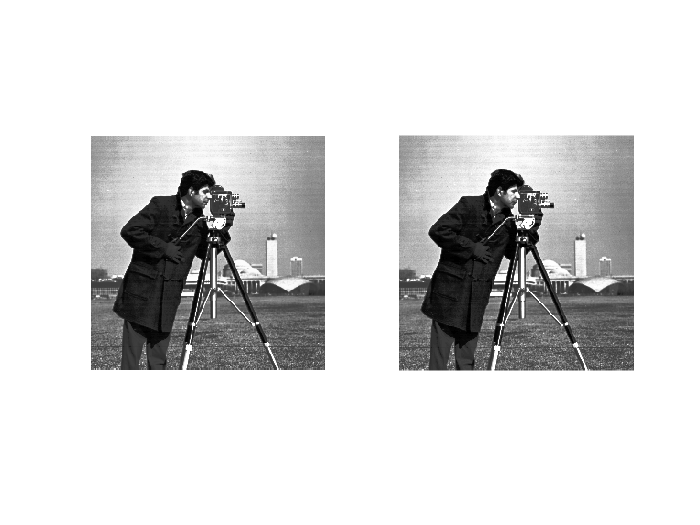

figure()
subplot(1,2,1); imshow(cm_h/255)
subplot(1,2,2); imshow(histeq(cm))